clear
rosshutdown

Shutting down global node /matlab_global_node_64353 with NodeURI http://192.168.1.100:52527/


setenv('ROS_MASTER_URI','http://192.168.1.200:11311')
setenv('ROS_IP','192.168.1.100')
rosinit('http://192.168.1.200:11311');

The value of the ROS_IP environment variable, 192.168.1.100, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_90977 with NodeURI http://192.168.1.100:52903/


path = [0 0; 0 0.5; 0 1; 0 1.5; 0 2; 0.5 2; 1 2; 1.5 2; 2 2;2 1.5; 2 1; 2 0.5; 2 0; 2 0;1.5 0;1 0;0.5 0];
robotInitialLocation = path(1,:);
robotGoal = path(end,:);
initialOrientation = 0;
robotCurrentPose = [robotInitialLocation, initialOrientation]';

robot = differentialDriveKinematics("TrackWidth", 0.5, "VehicleInputs", "VehicleSpeedHeadingRate");

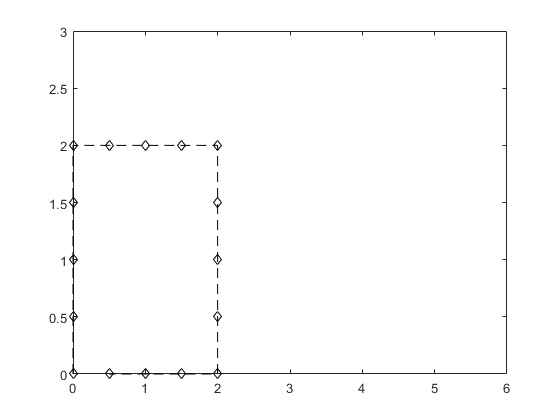

figure
plot(path(:,1), path(:,2),'k--d')
xlim([0 6])
ylim([0 3])

controller = controllerPurePursuit;

controller.Waypoints = path;

controller.DesiredLinearVelocity = 0.5;

controller.MaxAngularVelocity = 2;

controller.LookaheadDistance = 0.3;

goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);

% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/0.8;

while( distanceToGoal > goalRadius )
    
    velocity = 0.5;

    robotRealLife = rospublisher('/mobile_base/commands/velocity');
    velmsg = rosmessage(robotRealLife);

    velmsg.Linear.X = velocity;
    
    send(robotRealLife,velmsg);
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:))
    
    waitfor(vizRate);
end

robotCurrentPose =     0.0600
         0
    0.2000


distanceToGoal = 0.4400

robotCurrentPose =     0.1188
    0.0119
    0.4000


distanceToGoal = 0.3814

robotCurrentPose =     0.1741
    0.0353
    0.6000


distanceToGoal = 0.3278

robotCurrentPose =     0.2236
    0.0692
    0.8000


distanceToGoal = 0.2849

robotCurrentPose =     0.2654
    0.1122
    1.0000


distanceToGoal = 0.2601

robotCurrentPose =     0.2978
    0.1627
    1.2000


distanceToGoal = 0.2595

robotCurrentPose =     0.3195
    0.2186
    1.4000


distanceToGoal = 0.2835

robotCurrentPose =     0.3297
    0.2777
    1.6000


distanceToGoal = 0.3258

robotCurrentPose =     0.3280
    0.3377
    1.8000


distanceToGoal = 0.3790

robotCurrentPose =     0.3144
    0.3961
    2.0000


distanceToGoal = 0.4375

robotCurrentPose =     0.2894
    0.4507
    2.2000


distanceToGoal = 0.4975

robotCurrentPose =     0.2541
    0.4992
    2.2918


distanceToGoal = 0.5565

robotCurrentPose =     0.2145
    0.5443
    2.2796


distanceToGoal = 0.6146

robotCurrentPose =     0.1754
    0.5898
    2.2209


distanceToGoal = 0.6732

robotCurrentPose =     0.1391
    0.6376
    2.1404


distanceToGoal = 0.7326

robotCurrentPose =     0.1067
    0.6881
    2.0504


distanceToGoal = 0.7926

robotCurrentPose =     0.0791
    0.7413
    1.9588


distanceToGoal = 0.8525

robotCurrentPose =     0.0564
    0.7969
    1.8722


distanceToGoal = 0.9121

robotCurrentPose =     0.0385
    0.8542
    1.7952


distanceToGoal = 0.9709

robotCurrentPose =     0.0252
    0.9127
    1.7309


distanceToGoal = 1.0288

robotCurrentPose =     0.0156
    0.9719
    1.6801


distanceToGoal = 1.0859

robotCurrentPose =     0.0091
    1.0316
    1.6419


distanceToGoal = 1.1424

robotCurrentPose =     0.0048
    1.0914
    1.6147


distanceToGoal = 1.1985

robotCurrentPose =     0.0022
    1.1513
    1.5961


distanceToGoal = 1.2544

robotCurrentPose =     0.0007
    1.2113
    1.5841


distanceToGoal = 1.3102

robotCurrentPose =    -0.0001
    1.2713
    1.5767


distanceToGoal = 1.3662

robotCurrentPose =    -0.0005
    1.3313
    1.5725


distanceToGoal = 1.4223

robotCurrentPose =    -0.0006
    1.3913
    1.5703


distanceToGoal = 1.4786

robotCurrentPose =    -0.0006
    1.4513
    1.5693


distanceToGoal = 1.5352

robotCurrentPose =    -0.0005
    1.5113
    1.5691


distanceToGoal = 1.5920

robotCurrentPose =    -0.0004
    1.5713
    1.5692


distanceToGoal = 1.6491

robotCurrentPose =    -0.0003
    1.6313
    1.5694


distanceToGoal = 1.7063

robotCurrentPose =    -0.0002
    1.6913
    1.5698


distanceToGoal = 1.7637

robotCurrentPose =    -0.0001
    1.7513
    1.5700


distanceToGoal = 1.8213

robotCurrentPose =    -0.0001
    1.8113
    1.4355


distanceToGoal = 1.8791

robotCurrentPose =     0.0080
    1.8708
    1.2355


distanceToGoal = 1.9344

robotCurrentPose =     0.0278
    1.9274
    1.0355


distanceToGoal = 1.9844

robotCurrentPose =     0.0584
    1.9790
    0.8355


distanceToGoal = 2.0277

robotCurrentPose =     0.0986
    2.0235
    0.6355


distanceToGoal = 2.0630

robotCurrentPose =     0.1469
    2.0591
    0.4355


distanceToGoal = 2.0892

robotCurrentPose =     0.2013
    2.0845
    0.2355


distanceToGoal = 2.1057

robotCurrentPose =     0.2596
    2.0985
    0.0355


distanceToGoal = 2.1122

robotCurrentPose =     0.3196
    2.1006
   -0.1645


distanceToGoal = 2.1083

robotCurrentPose =     0.3788
    2.0908
   -0.2701


distanceToGoal = 2.0943

robotCurrentPose =     0.4366
    2.0748
   -0.2859


distanceToGoal = 2.0757

robotCurrentPose =     0.4942
    2.0578
   -0.2581


distanceToGoal = 2.0578

robotCurrentPose =     0.5522
    2.0425
   -0.2130


distanceToGoal = 2.0432

robotCurrentPose =     0.6108
    2.0298
   -0.1649


distanceToGoal = 2.0329

robotCurrentPose =     0.6700
    2.0200
   -0.1211


distanceToGoal = 2.0271

robotCurrentPose =     0.7296
    2.0127
   -0.0847


distanceToGoal = 2.0258

robotCurrentPose =     0.7894
    2.0077
   -0.0565


distanceToGoal = 2.0284

robotCurrentPose =     0.8493
    2.0043
   -0.0359


distanceToGoal = 2.0345

robotCurrentPose =     0.9092
    2.0021
   -0.0214


distanceToGoal = 2.0435

robotCurrentPose =     0.9692
    2.0008
   -0.0119


distanceToGoal = 2.0551

robotCurrentPose =     1.0292
    2.0001
   -0.0058


distanceToGoal = 2.0690

robotCurrentPose =     1.0892
    1.9998
   -0.0022


distanceToGoal = 2.0848

robotCurrentPose =     1.1492
    1.9996
   -0.0002


distanceToGoal = 2.1024

robotCurrentPose =     1.2092
    1.9996
    0.0007


distanceToGoal = 2.1217

robotCurrentPose =     1.2692
    1.9997
    0.0011


distanceToGoal = 2.1425

robotCurrentPose =     1.3292
    1.9997
    0.0011


distanceToGoal = 2.1648

robotCurrentPose =     1.3892
    1.9998
    0.0010


distanceToGoal = 2.1886

robotCurrentPose =     1.4492
    1.9999
    0.0008


distanceToGoal = 2.2137

robotCurrentPose =     1.5092
    1.9999
    0.0006


distanceToGoal = 2.2401

robotCurrentPose =     1.5692
    1.9999
    0.0004


distanceToGoal = 2.2678

robotCurrentPose =     1.6292
    2.0000
    0.0003


distanceToGoal = 2.2967

robotCurrentPose =     1.6892
    2.0000
    0.0002


distanceToGoal = 2.3268

robotCurrentPose =     1.7492
    2.0000
    0.0001


distanceToGoal = 2.3581

robotCurrentPose =     1.8092
    2.0000
   -0.1283


distanceToGoal = 2.3904

robotCurrentPose =     1.8687
    1.9923
   -0.3283


distanceToGoal = 2.4172

robotCurrentPose =     1.9255
    1.9730
   -0.5283


distanceToGoal = 2.4341

robotCurrentPose =     1.9773
    1.9427
   -0.7283


distanceToGoal = 2.4406

robotCurrentPose =     2.0221
    1.9028
   -0.9283


distanceToGoal = 2.4367

robotCurrentPose =     2.0581
    1.8547
   -1.1283


distanceToGoal = 2.4223

robotCurrentPose =     2.0838
    1.8005
   -1.3283


distanceToGoal = 2.3980

robotCurrentPose =     2.0982
    1.7423
   -1.5283


distanceToGoal = 2.3642

robotCurrentPose =     2.1007
    1.6823
   -1.7283


distanceToGoal = 2.3222

robotCurrentPose =     2.0913
    1.6231
   -1.8387


distanceToGoal = 2.2730

robotCurrentPose =     2.0754
    1.5652
   -1.8571


distanceToGoal = 2.2208

robotCurrentPose =     2.0585
    1.5077
   -1.8304


distanceToGoal = 2.1684

robotCurrentPose =     2.0431
    1.4497
   -1.7857


distanceToGoal = 2.1172

robotCurrentPose =     2.0303
    1.3911
   -1.7375


distanceToGoal = 2.0680

robotCurrentPose =     2.0203
    1.3319
   -1.6935


distanceToGoal = 2.0212

robotCurrentPose =     2.0130
    1.2723
   -1.6568


distanceToGoal = 1.9768

robotCurrentPose =     2.0078
    1.2126
   -1.6283


distanceToGoal = 1.9349

robotCurrentPose =     2.0044
    1.1527
   -1.6073


distanceToGoal = 1.8952

robotCurrentPose =     2.0022
    1.0927
   -1.5927


distanceToGoal = 1.8576

robotCurrentPose =     2.0009
    1.0327
   -1.5830


distanceToGoal = 1.8218

robotCurrentPose =     2.0001
    0.9727
   -1.5768


distanceToGoal = 1.7879

robotCurrentPose =     1.9998
    0.9127
   -1.5731


distanceToGoal = 1.7557

robotCurrentPose =     1.9996
    0.8527
   -1.5711


distanceToGoal = 1.7251

robotCurrentPose =     1.9996
    0.7927
   -1.5701


distanceToGoal = 1.6963

robotCurrentPose =     1.9997
    0.7327
   -1.5697


distanceToGoal = 1.6691

robotCurrentPose =     1.9997
    0.6727
   -1.5697


distanceToGoal = 1.6437

robotCurrentPose =     1.9998
    0.6127
   -1.5698


distanceToGoal = 1.6201

robotCurrentPose =     1.9999
    0.5527
   -1.5700


distanceToGoal = 1.5985

robotCurrentPose =     1.9999
    0.4927
   -1.5702


distanceToGoal = 1.5788

robotCurrentPose =     1.9999
    0.4327
   -1.5704


distanceToGoal = 1.5611

robotCurrentPose =     2.0000
    0.3727
   -1.5705


distanceToGoal = 1.5456

robotCurrentPose =     2.0000
    0.3127
   -1.5706


distanceToGoal = 1.5322

robotCurrentPose =     2.0000
    0.2527
   -1.5707


distanceToGoal = 1.5211

robotCurrentPose =     2.0000
    0.1927
   -1.6933


distanceToGoal = 1.5123

robotCurrentPose =     1.9927
    0.1332
   -1.8933


distanceToGoal = 1.4986

robotCurrentPose =     1.9736
    0.0763
   -2.0933


distanceToGoal = 1.4756

robotCurrentPose =     1.9437
    0.0243
   -2.2933


distanceToGoal = 1.4439

robotCurrentPose =     1.9040
   -0.0207
   -2.4933


distanceToGoal = 1.4042

robotCurrentPose =     1.8562
   -0.0570
   -2.6933


distanceToGoal = 1.3574

robotCurrentPose =     1.8021
   -0.0830
   -2.8933


distanceToGoal = 1.3048

robotCurrentPose =     1.7440
   -0.0977
   -3.0933


distanceToGoal = 1.2478

robotCurrentPose =     1.6840
   -0.1006
   -3.2933


distanceToGoal = 1.1883

robotCurrentPose =     1.6247
   -0.0915
   -3.4073


distanceToGoal = 1.1284

robotCurrentPose =     1.5668
   -0.0758
   -3.4276


distanceToGoal = 1.0695

robotCurrentPose =     1.5093
   -0.0589
   -3.4019


distanceToGoal = 1.0110

robotCurrentPose =     1.4513
   -0.0434
   -3.3575


distanceToGoal = 0.9523

robotCurrentPose =     1.3927
   -0.0306
   -3.3094


distanceToGoal = 0.8932

robotCurrentPose =     1.3335
   -0.0205
   -3.2652


distanceToGoal = 0.8338

robotCurrentPose =     1.2740
   -0.0131
   -3.2284


distanceToGoal = 0.7741

robotCurrentPose =     1.2142
   -0.0079
   -3.1997


distanceToGoal = 0.7142

robotCurrentPose =     1.1543
   -0.0044
   -3.1786


distanceToGoal = 0.6543

robotCurrentPose =     1.0943
   -0.0022
   -3.1638


distanceToGoal = 0.5943

robotCurrentPose =     1.0344
   -0.0009
   -3.1540


distanceToGoal = 0.5344

robotCurrentPose =     0.9744
   -0.0002
   -3.1477


distanceToGoal = 0.4744

robotCurrentPose =     0.9144
    0.0002
   -3.1440


distanceToGoal = 0.4144

robotCurrentPose =     0.8544
    0.0004
   -3.1419


distanceToGoal = 0.3544

robotCurrentPose =     0.7944
    0.0004
   -3.1409


distanceToGoal = 0.2944

robotCurrentPose =     0.7344
    0.0003
   -3.1405


distanceToGoal = 0.2344

robotCurrentPose =     0.6744
    0.0003
   -3.1403


distanceToGoal = 0.1744

robotCurrentPose =     0.6144
    0.0002
   -3.1401


distanceToGoal = 0.1144

robotCurrentPose =     0.5544
    0.0001
   -3.1400


distanceToGoal = 0.0544

velocity = 0;
velmsg.Linear.X = velocity;
send(robotRealLife, velmsg)